1)Напишите скрипт, переставляющий элементы вектора в обратном      порядке и записывающий результат в новый вектор.

a = input('введите вектор а: \n')

a =      2     3     4     1


disp('вектора в обратном порядке')

вектора в обратном порядке


b = flip(a);
disp(b)

     1     4     3     2



2)Напишите скрипт, выделяющий из вектора 2 новых вектора,     содержащие чётные (первый вектор) и нечётные (второй) элементы исходного вектора. 

a = input('введите вектор а: \n')

a =      1     2     4     5     6     7    12    22    33    44


a1=[];
a2=[];
for i = 1:length(a)
    if(mod(a(i),2) == 0)
        a1 = [a1,a(i)];
    else
        a2 = [a2,a(i)];
    end
end
disp('Четные')
disp(a1)

     2     4     6    12    22    44



disp('Нечетные')
disp(a2)

     1     5     7    33



3) Создайте скрипт, находящий сумму отрицательных элементов вектора.

a = input('введите вектор а: \n')

a =     -1     1     2     3    -3


a1=0;
for i = 1:length(a)
    if(a(i) < 0)
        a1 = a1 + a(i);
    end
end
disp('сумму отрицательных элементов вектора')

сумму отрицательных элементов вектора


disp(a1)

    -4



4)Создайте скрипт, заменяющий элементы вектора, отличающиеся от среднего геометрического его элементов более, чем на 15%, на это среднее геометрическое.

a = input('введите вектор а: \n')

a =      1     2     3     4


gm = geomean(a);
for i = 1:length(a)
    if(abs(gm - a(i)) > 0.15*gm)
        a(i) = gm;
    end
end
disp('Ответ')

Ответ


disp(a)

    2.2134    2.0000    2.2134    2.2134



5)Напишите скрипт, заменяющий все минимальные элементы вектора максимальным значением его элементов.

a = input('введите вектор а: \n')

a =      1     2     3     6     1     8     8     8     1


maxa = max(a);
mina = min(a);
for i = 1:length(a)
    if(a(i) == mina)
        a(i) = maxa;
    end
end
disp('Ответ')

Ответ


disp(a)

     8     2     3     6     8     8     8     8     8



6)Разработайте скрипт, ищущий и выводящий число положительных, нулевых и отрицательных элементов входной матрицы.

a = input('введите вектор а: \n')

a =      1     2     3     6     1     8     8     8     1


s = size(a);
negative =0;
pos = 0;
zero =0;
for i = 1:s(1)
    for j = 1:s(2)
        if(a(i,j) > 0)
            pos = pos + 1;
        else if(a(i,j) < 0)
            negative = negative +1;
        else
            zero  = zero +1;
        end
    end
    end
end
disp('Отрицательный')

Отрицательный


disp(negative)

     0



disp('Положительный')

Положительный


disp(pos)

     9



disp('Ноль')

Ноль


disp(zero)

     0



7)Решите систему уравнений 2x1+3x2+3x3=8; 4x1+2x2+3x3=7; 6x1+5x2+6x3=7методом x=A\b. Затем найдите число обусловленности матрицы (функция cond(A)), убедитесь в неправильности найденного решения (сделайте проверку) и решите систему методом Гаусса. 

syms x1 x2 x3
eq1 =  2*x1+3*x2+3*x3 == 8;
eq2 =  4*x1+2*x2+3*x3 == 7;
eq3 =  6*x1+5*x2+6*x3 == 7;
[A,B] = equationsToMatrix([eq1, eq2, eq3], [x1, x2, x3]);
X = A\B

$$X = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

cond(A)

$$ans = \infty$$

if(cond(A) > 10000000000000000000000)
    disp('Нет решение!')
else
    disp('Есть решение!')
end

Нет решение!


rref([A B])

$$ans = \left(\begin{array}{cccc} 1 & 0 & \frac{3}{8} & 0\\ 0 & 1 & \frac{3}{4} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

8)Дана табличная функция y(t)=a*e^(-t)+b*t: t=[0 0.1 0.2 0.3 0.4 0.5], y=[4.25 3.95 3.64 3.41 3.21 3.04] (т.е. переопределённая система 6 уравнений для 2 неизвестных: a и b). Решите эту систему с помощью \, постройте графики функции: по точкам y(t) и линией (fplot)согласно найденным a и b.  

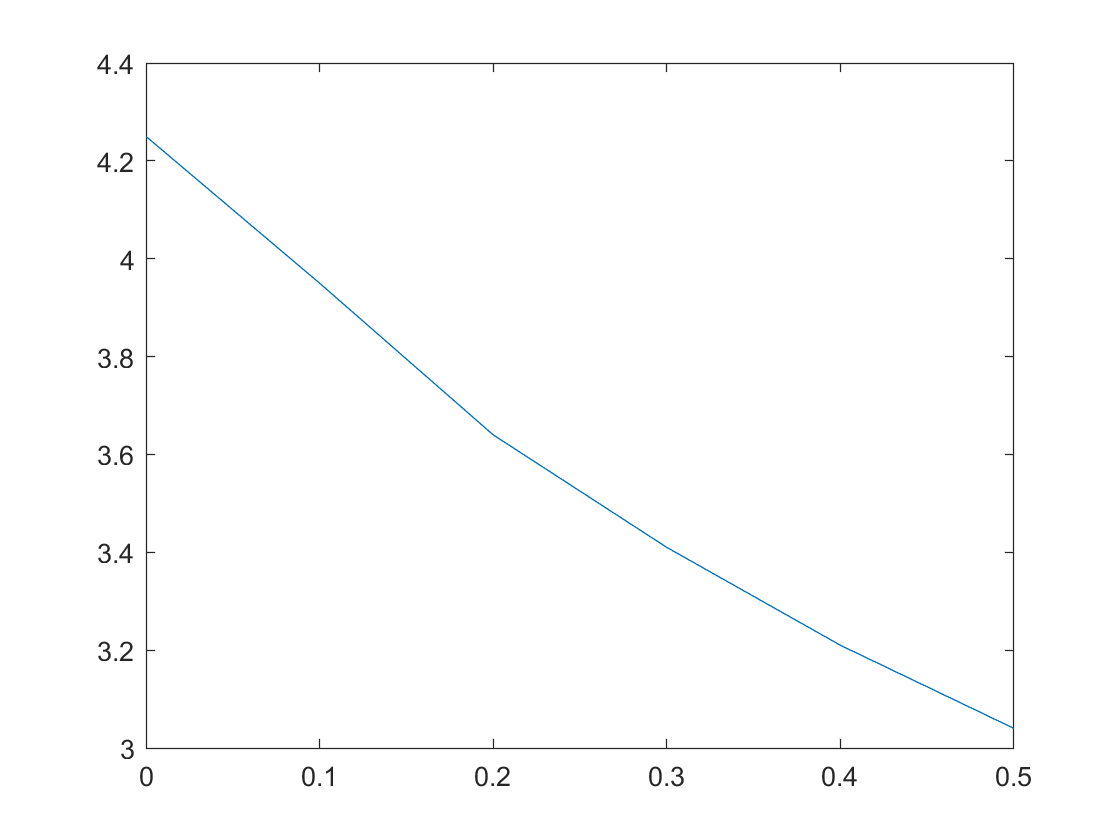

t=[0 0.1 0.2 0.3 0.4 0.5];
t1 = exp(-t);
y=[4.25 3.95 3.64 3.41 3.21 3.04];
A = [t1;t]';
X = A\y';
a = X(1,1);
b = X(2,1);
plot(t,y)

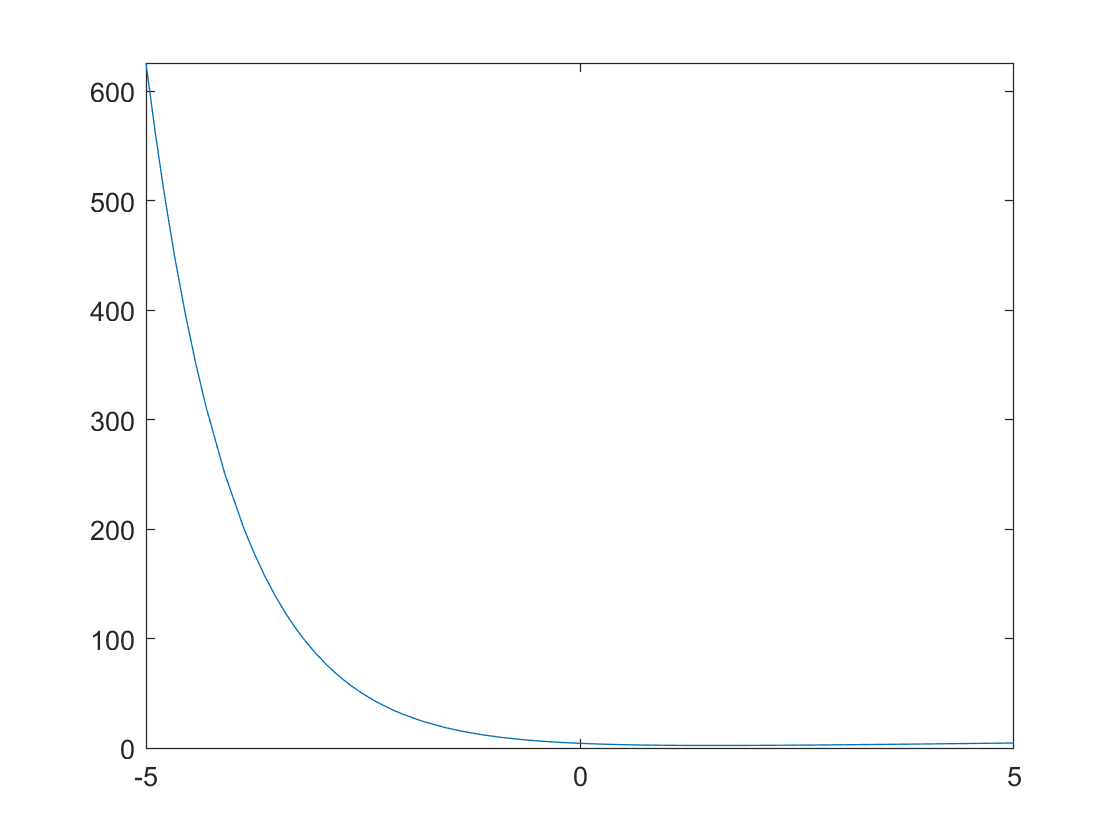

f = @(x) a * exp(-x) + b * x;
fplot(f)

9)Решите недоопределённуюсистему уравнений x1+2x2+3x3=2; 3x1+4x2+5x3=2 (\). Проверьте решение, умножив матрицу системы (А) на него.

syms x1 x2 x3
eq1 =   x1+2*x2+3*x3==2

$$eq1 = x_{1}+2\,x_{2}+3\,x_{3}=2$$

eq2 =  3*x1+4*x2+5*x3==2

$$eq2 = 3\,x_{1}+4\,x_{2}+5\,x_{3}=2$$

[A,B] = equationsToMatrix([eq1, eq2], [x1, x2, x3]);
X = A\B

$$X = \left(\begin{array}{c} -2\\ 2\\ 0 \end{array}\right)$$

A * X

$$ans = \left(\begin{array}{c} 2\\ 2 \end{array}\right)$$

10)Решите систему линейных уравнений 2x1+3x2+3x3=8; -2x1-3x2-3x3=7 с помощью функции linsolve.

syms x1 x2 x3
eq1 =   2*x1+3*x2+3*x3==8;
eq2 =   -2*x1-3*x2-3*x3==7;
[A,B] = equationsToMatrix([eq1, eq2], [x1, x2, x3]);
X = linsolve(A,B)

$$X = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

$$ans = \left(\begin{array}{cccc} 1 & \frac{3}{2} & \frac{3}{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

11)Решите систему из п.10 с помощью QR-разложения.

syms x1 x2 x3
eq1 =   2*x1+3*x2+3*x3==8;
eq2 =   -2*x1-3*x2-3*x3==7;
[A,B] = equationsToMatrix([eq1, eq2], [x1, x2, x3]);
[q,r]=qr(A);
X = r \ (q' * B)

$$X = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

12)Вычислите все собственные векторы и числа матрицы A [2 4 5; 3 6 7; 8 5 2].Выведите их по очереди, записав в отдельные векторы и переменные. Проверьте, правильно ли найден первый собственный вектор и соответствующее ему собственное число.

A = [2 4 5; 3 6 7; 8 5 2];
[x,y] = eig(A)

x =    -0.4610   -0.3792   -0.3627
   -0.6709    0.7849   -0.4491
   -0.5809   -0.4900    0.8165


y =    14.1226         0         0
         0    0.1810         0
         0         0   -4.3035


ea1 = y(1,1)

ea1 = 14.1226

ev1 = x(:,1)

ev1 =    -0.4610
   -0.6709
   -0.5809


ea2 = y(2,2)

ea2 = 0.1810

ev2 = x(:,2)

ev2 =    -0.3792
    0.7849
   -0.4900


ea3 = y(3,3)

ea3 = -4.3035

ev3 = x(:,3)

ev3 =    -0.3627
   -0.4491
    0.8165


A - ea1.*eye(3)

ans =   -12.1226    4.0000    5.0000
    3.0000   -8.1226    7.0000
    8.0000    5.0000  -12.1226


if(round(det(A - ea1*eye(3))) == 0)
    disp('Правильно нашли собственное значение')
end

Правильно нашли собственное значение


c = (A * ev1) ./ ev1

c =    14.1226
   14.1226
   14.1226


c = round(c,3)

c =    14.1230
   14.1230
   14.1230


if(c(1,1) == c(2,1) && c(2,1) == c(3,1))
    disp('Верно!')
end

Верно!
